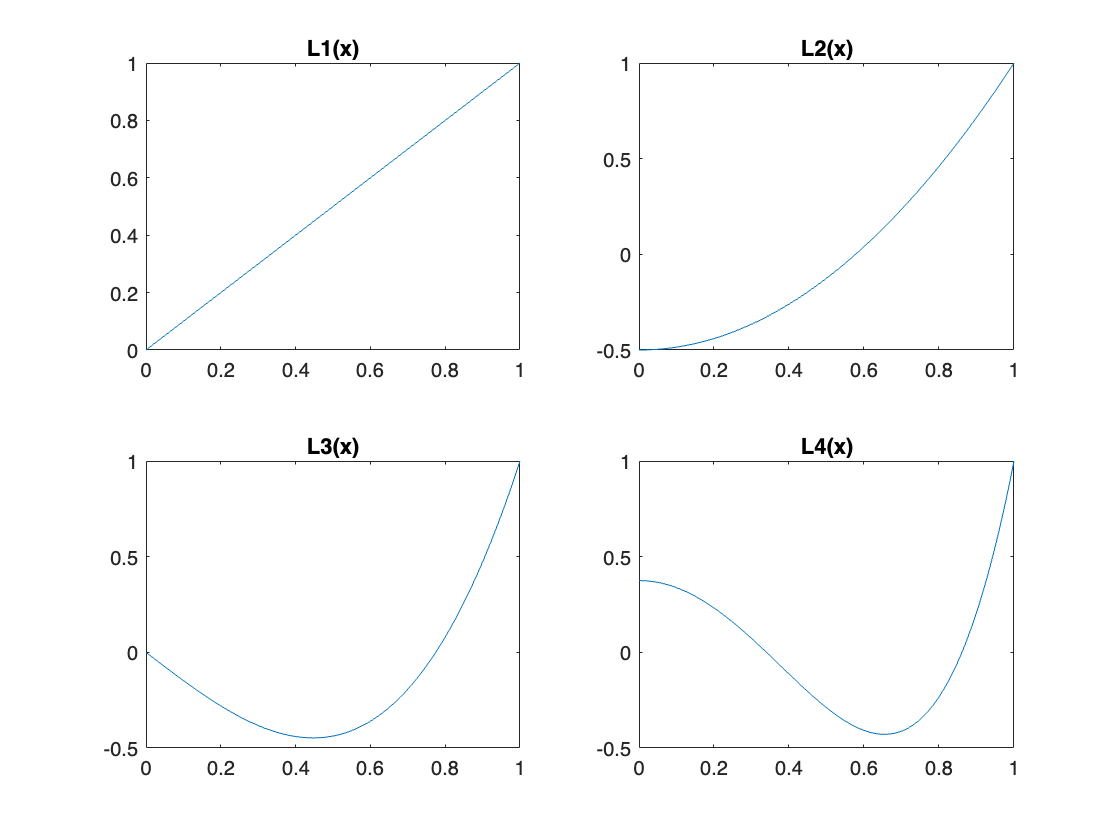

x = 0:0.01:1; 

l1 = x;
l2 = (3/2)*x.^2 - 1/2;
l3 = (5/2)*x.^3 - (3/2)*x;
l4 = (35/8)*x.^4 - (15/4)*x.^2 + 3/8;

subplot(2,2,1), plot(x, l1), title('L1(x)');
subplot(2,2,2), plot(x, l2), title('L2(x)');
subplot(2,2,3), plot(x, l3), title('L3(x)');
subplot(2,2,4), plot(x, l4), title('L4(x)');

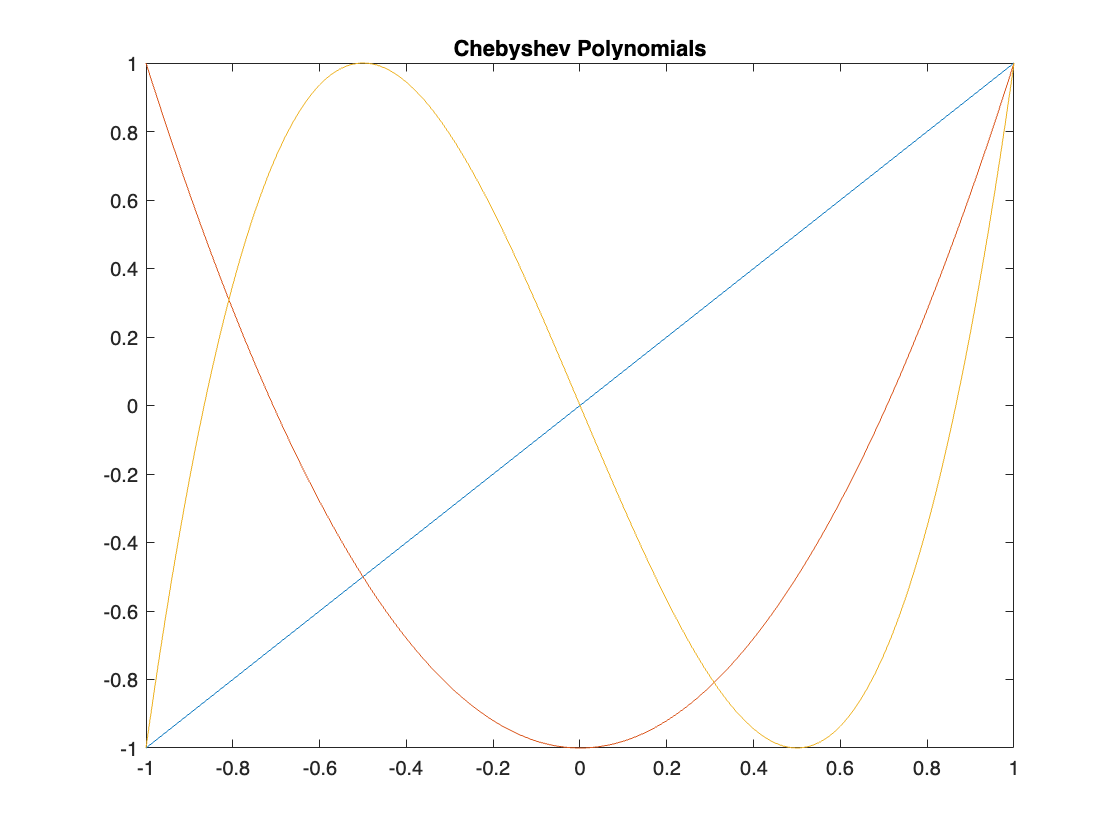

x = -1:0.01:1; 

T1 = cos(1 * acos(x));
T2 = cos(2 * acos(x));
T3 = cos(3 * acos(x));

figure;
plot(x, T1, x, T2, x, T3);
title('Chebyshev Polynomials');

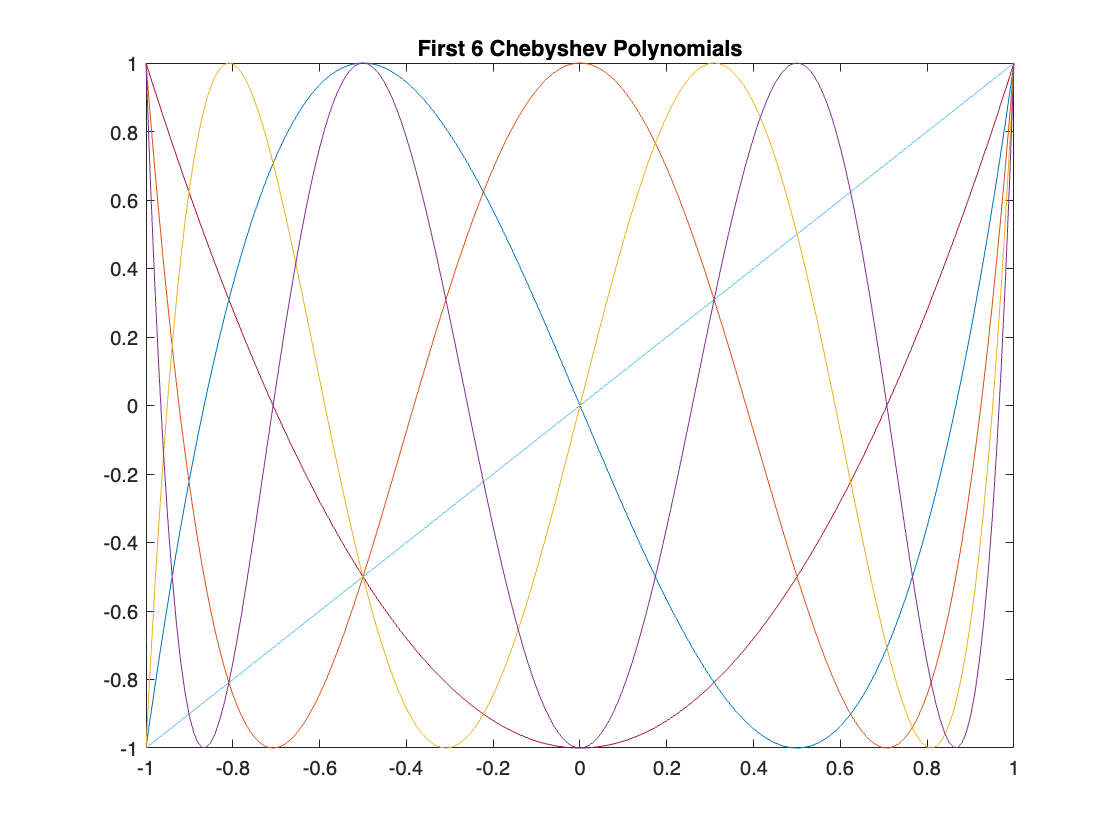

n = 6;
x = -1:0.01:1; 

T0 = 1;
T1 = x; 
T2 = 2*x.*T1 - T0;
T3 = 2*x.*T2 - T1;
T4 = 2*x.*T3 - T2;
T5 = 2*x.*T4 - T3;
T6 = 2*x.*T5 - T4;

plot(x, T0, x, T1, x, T2,x, T3, x, T4, x, T5, x, T6);
title('First 6 Chebyshev Polynomials');

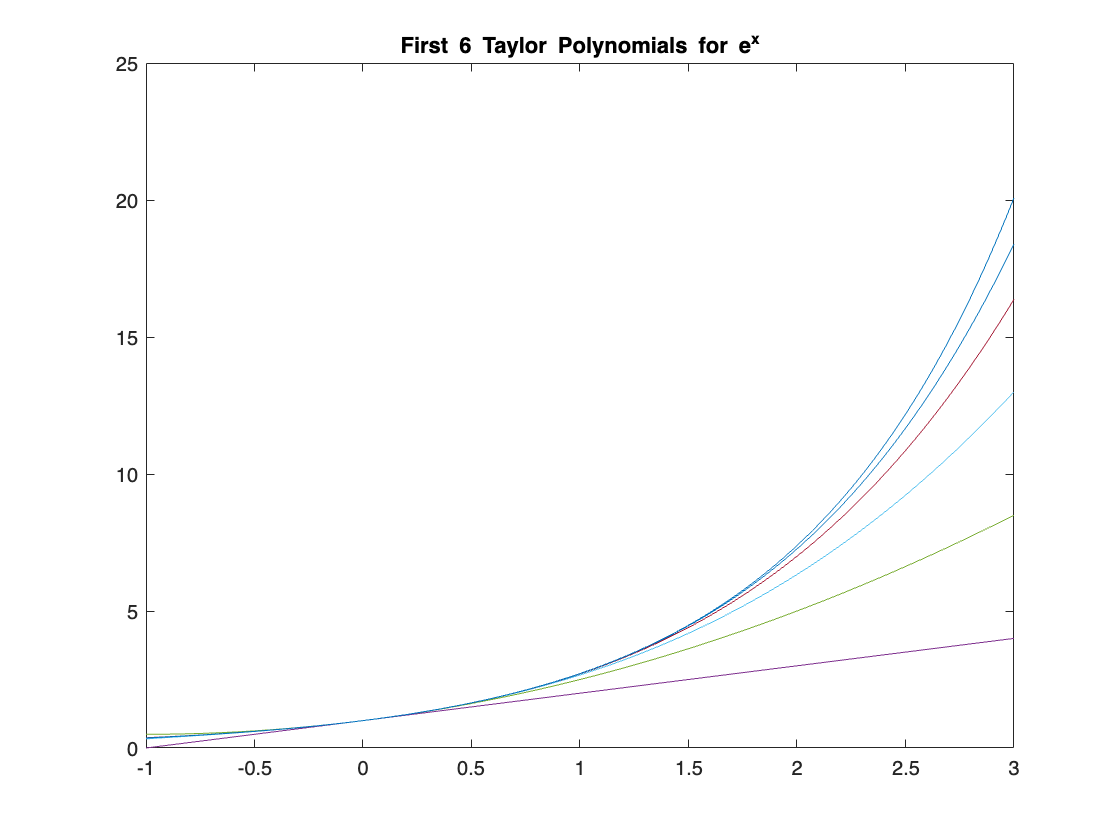

x = -1:0.01:3;
f = exp(x);

P0 = 1;
P1 = P0 + x;
P2 = P1 + (x.^2)/2;
P3 = P2 + (x.^3)/6;
P4 = P3 + (x.^4)/24;
P5 = P4 + (x.^5)/120;

figure;
plot(x, f, x, P0, x, P1, x, P2, x, P3, x, P4, x, P5);
title('First 6 Taylor Polynomials for e^x');

h = 0.25;
x = 1:0.01:2.5;
xi = 1 + (0:6)*h;
f = sqrt(5*xi.^2 + 1);

n = length(xi);
table = zeros(n, n);
table(:,1) = f';

for j = 2:n
    for i = 1:n-j+1
        table(i,j) = table(i+1,j-1) - table(i,j-1);
    end
end

disp(table);

    2.4495    0.5191    0.0123   -0.0049    0.0022   -0.0011    0.0006
    2.9686    0.5314    0.0075   -0.0026    0.0011   -0.0005         0
    3.5000    0.5389    0.0048   -0.0015    0.0006         0         0
    4.0389    0.5437    0.0033   -0.0010         0         0         0
    4.5826    0.5470    0.0023         0         0         0         0
    5.1296    0.5493         0         0         0         0         0
    5.6789         0         0         0         0         0         0



x = [2, 4, 6, 8]; 
f = [4, 8, 14, 16];

n = length(x);
table = zeros(n, n);
table(:,1) = f'; 

for j = 2:n
    for i = 1:n-j+1
        table(i,j) = (table(i+1,j-1) - table(i,j-1)) / (x(i+j-1) - x(i));
    end
end

disp(table);

    4.0000    2.0000    0.2500   -0.1250
    8.0000    3.0000   -0.5000         0
   14.0000    1.0000         0         0
   16.0000         0         0         0

